# Raúl Correa Ocañas

Actividad 2

A01722401

23 de mayo de 2023

clc
dydx = @(x,y) y*x.^2-1.1*y ; % eq dif
y(1) = 1; % y inicial
h = 0.25; % Paso delta h
x_1 = 0; % x inicial
x_f = 2; % x final

[x, y_heun] = Heun(dydx,x_1,x_f,y,h);
[x, y_mid] = PuntoMedio(dydx,x_1,x_f,y,h);
[x, y_ralston] = Ralston(dydx,x_1,x_f,y,h);
[x, y_RK3] = RK3(dydx,x_1,x_f,y,h);
[x, y_RK4] = RK4(dydx,x_1,x_f,y,h);
[x, y_real] = Real(x_1,x_f,h);

y_heun

y_heun =     1.0000    0.7685    0.6083    0.5115    0.4716    0.4923    0.5997    0.8753    1.5631


y_mid

y_mid =     1.0000    0.7662    0.6062    0.5102    0.4704    0.4896    0.5920    0.8528    1.4941


y_ralston

y_ralston =     1.0000    0.7675    0.6075    0.5111    0.4712    0.4912    0.5961    0.8643    1.5287


y_RK3

y_RK3 =     1.0000    0.7634    0.6014    0.5045    0.4649    0.4856    0.5929    0.8727    1.5939


y_RK4

y_RK4 =     1.0000    0.7635    0.6015    0.5044    0.4646    0.4848    0.5916    0.8705    1.5937


y_real

y_real =     1.0000    0.7635    0.6015    0.5044    0.4646    0.4848    0.5916    0.8706    1.5947


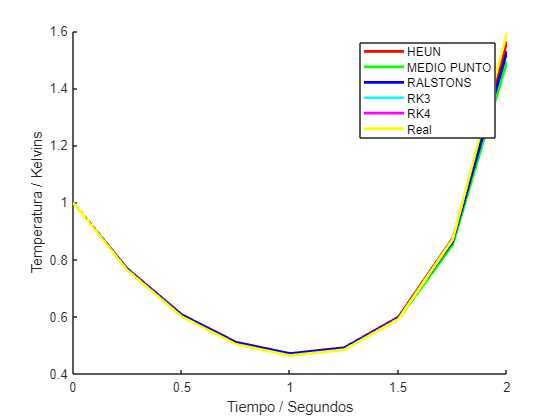

figure(1)
hold on
a1 = plot(x, y_heun, 'r', 'LineWidth', 2);    % Heun - rojo
a2 = plot(x, y_mid, 'g', 'LineWidth', 2);     % Medio Punto - verde
a3 = plot(x, y_ralston, 'b', 'LineWidth', 2); % Ralston's - azul
a4 = plot(x, y_RK3, 'c', 'LineWidth', 2); % RK3 - celeste
a5 = plot(x, y_RK4, 'm', 'LineWidth', 2); % RK4 - morado
a6 = plot(x, y_RK4, 'y', 'LineWidth', 2); % Real - amarillo

hold off

xlabel('Tiempo / Segundos')
ylabel('Temperatura / Kelvins')
legend([a1,a2,a3,a4,a5,a6], 'HEUN', 'MEDIO PUNTO', 'RALSTONS', 'RK3', 'RK4','Real')

## Método de Heun

function [x,y] = Heun(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h, y(i) + k1*h);
        y(i+1) = y(i) + h*(k1 + k2)/2;
    end
end

## Método de Punto Medio

function [x,y] = PuntoMedio(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        y(i+1) = y(i) + k2*h;
    end
end

## Método de Ralston

function [x,y] = Ralston(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + 3*h/4, y(i) + 3*k1*h/4);
        y(i+1) = y(i) + (k1 + 2*k2)*h/3;
    end
end

## Método de Runge Kutta Orden 3

function [x,y] = RK3(f,x_1,x_f,y,h)
    x = x_1:h:x_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        k3 = f(x(i) + h, y(i) - k1*h + 2*k2*h);
        y(i+1) = y(i) + (k1 + 4*k2 + k3)*h/6;
    end
end

## Método de Runge Kutta Orden 4

function [x,y] = RK4(f,x_1,x_f,y,h)
    x = x_1:h:x_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        k3 = f(x(i) + h/2, y(i) + k2*h/2);
        k4 = f(x(i) + h, y(i) + k3*h);
        y(i+1) = y(i) + (k1 + 2*k2 + 2*k3 + k4)*h/6;
    end
end

## Metodo Analítico

function [x,y] = Real(x_1,x_f,h)
    x = x_1:h:x_f;
    for i = 1:length(x)
        y(i) = exp((((x(i))^3)/3)-1.1*x(i));
    end
end